# [**Hand Tracking**](https://apmonitor.com/pds/index.php/Main/HandTracking)

**NOTE: Image Processing, Image Acquisition and Simulink Toolboxes will be needed for the following , along with MATLAB Support packages for webcam/external video device of your choice **

## Introduction

To detect objects or regions of interest in images and videos, there are several approaches relying on pure image processing and computer vision or data-driven techniques such as deep learning. In this script, we will explore both approaches. Objects can be identified in images and they can be tracked over a sequence of images (i.e. live or recorded videos). In this script, we will explore how to detect and track objects using color-based segmentation by acquiring live video feed from a webcam. Approaches below are derived from MATLAB documentation examples and the original examples are also linked

#### Image Processing

Before we begin with prcoessing data given from live video footage, it would perhaps be best to demonstrate some processing methods that are possible with static images. In the following code, a JPEG image of a hand will be downloaded and processed in such a way that the features, in this case, the different fingers, can be recognized and plotted on a graph.

clear
%%% Load hand image from a url 
url_img = 'http://apmonitor.com/pds/uploads/Main/hands.jpg';
outfilename = websave('hands.jpg',url_img)

outfilename = 'C:\Users\seant\MATLAB_new\Hand_Track_Proj\hands.jpg'

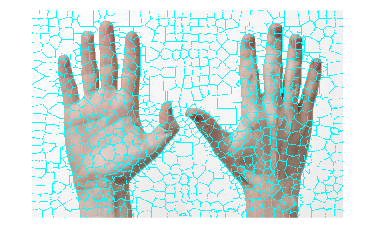


%%Read Image 
I = imread('hands.jpg');

%%%Computes superpixels for the image 
[L,N] = superpixels(I,1000); 

%%%%compute region boundaries for the input binary image
BW = boundarymask(L); 
imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);

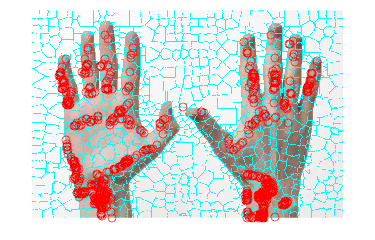


figure

%%%Following code based off of answer here: 
%%% https://www.mathworks.com/matlabcentral/answers/123639-finger-detection-from-binary-image
%%Binarize 
Ibw = imbinarize(I);

%%Fill in holes in binarized image
Ibw = imfill(Ibw,'holes');

%%%Convert binary into logical array
Ilabel = logical(Ibw);

%%% calculate coordinates for X & Y centroids
stat = regionprops(Ilabel,'centroid');

imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);  hold on;
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'ro');
end

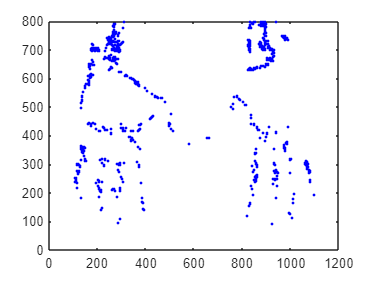

%%% Plot centroid points without background of hand image
figure
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'.b-');
    drawnow;
    hold on;
end


bwskel(Ibw)

ans = 800×1200×3 logical array
ans(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

#### Integration of Webcam with MATLAB

Now that you have worked with static image data, you are almost ready, though it is first useful to understand how a webcam or any external video device can be integrated into MATLAB code. In the following code, we will integrate a built in computer webcam with MATLAB code and display the video input in our live script.

**NOTE: The line "videoinput" may need to be modified be if you use an external video device. For more information, see **[**https://www.mathworks.com/help/supportpkg/usbwebcams/ug/webcam.html**](https://www.mathworks.com/help/supportpkg/usbwebcams/ug/webcam.html)

%%%%Clear any previous video object to allow camera to reaccess it 
%%%% If one exists and not cleared, then an error will be thrown
clear
imaqfind


ans =

     []



ans =   ToolboxPreferencesManager with properties:

    GetPrefListener: [1×1 handle.listener]
    SetPrefListener: [1×1 handle.listener]


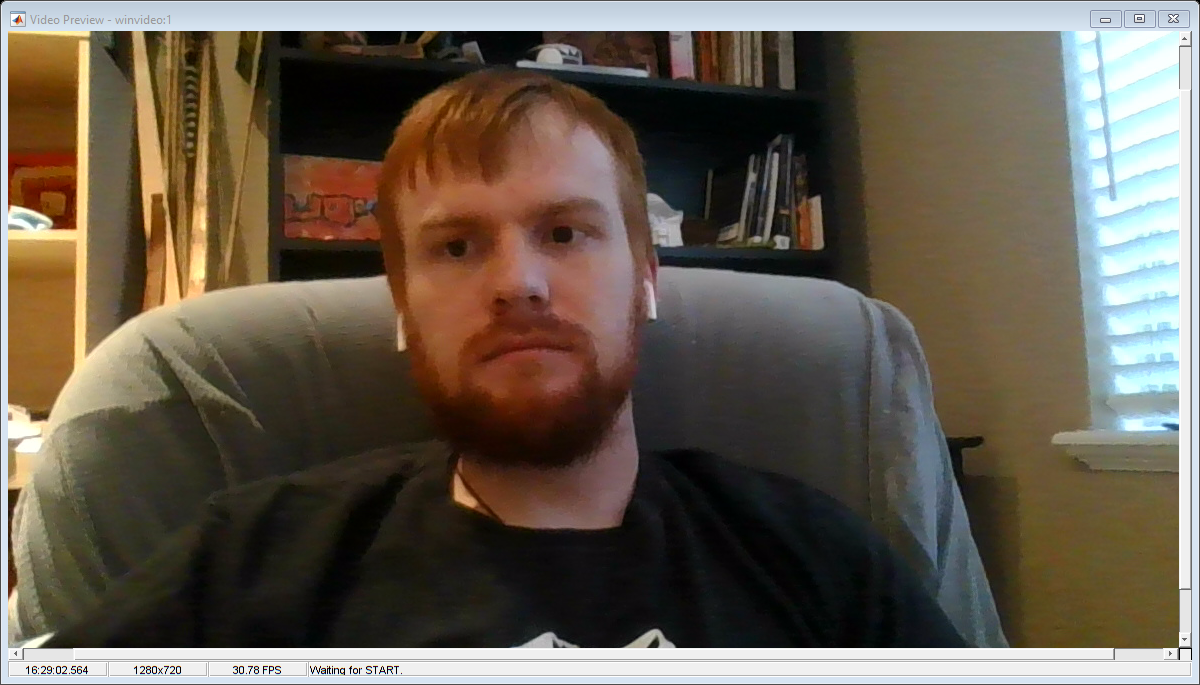

delete(imaqfind)

%%%%Connect to video camera
%%%% Note: This line may need to be modified if you are using an
%%%%% external video device
vid=videoinput('winvideo',1);                                             %sets videoinput to the webcam, and the webcam device 1
figure(3)

%%%% View your video input
preview(vid)                                                  %displays the webcam input

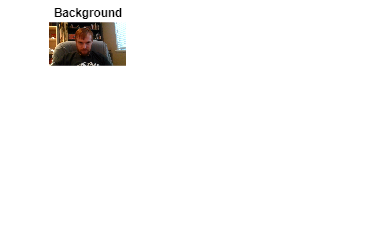


figure(1);

%%%% Display screnshot from the video input
set(vid,'ReturnedColorspace','rgb')
pause(3);                                                                 % pause 2 seconds before snapshot of background image
IM1=getsnapshot(vid);                                                     %get snapshot from the webcam video and store to IM1 variable
figure(1);subplot(3,3,1);imshow(IM1);title('Background'); %open up a figure and show the image stored in IM1 variable

## Varying Methods for Tracking Motion

Now that you have learned how to process static images and take in video input, you are ready to work with processing  live video feed in MATLAB.

With a video obejct created and in use, varying MATLAB methods can be used for tracking motion of specific body parts that are seen from live video.

#### Method 1: Face Detection with Cascade Object Detector

MATLAB's Cascade Object detector is a data driven approach to object detection, using positive and negative examples to recognize specific objects. MATLAB has several predesigned object detectors, such as the example here where they create one to recognize stop signs from image inputs:

[https://www.mathworks.com/help/vision/ug/train-a-cascade-object-detector.html#btu4ayz-1](https://www.mathworks.com/help/vision/ug/train-a-cascade-object-detector.html#btu4ayz-1)

MATLAB also has one that has the capabilities to recognize and track faces from video input. This can be run in the following code block:

%%% Get Current folder to preserve directory relationship
currFold = pwd; 
%%% Code and associated originally from: 
%%% https://www.mathworks.com/help/vision/ug/face-detection-and-tracking-using-live-video-acquisition.html
openExample('vision/FaceTrackingWebcamExample')

#### Method 2: Hand Tracking using Foreground Detection

MATLAB also has a built-in function that utilizes blob analysis in order to detect objects in the foreground of video input. This can thus be used to detect and track hand motion, which usually is foregrounded in video input of a person from a webcam.

**Note: For best results, move your hand between your face and the webcam/video device to see the hand detection in action.** 

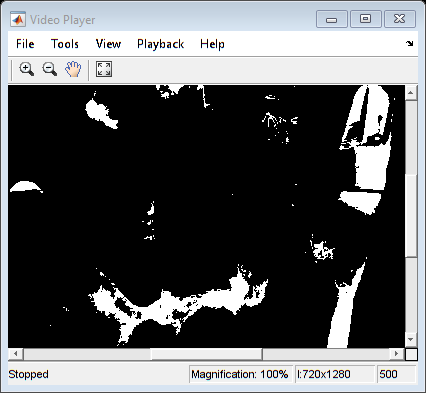

cd(currFold);
clear;
imaqfind;
delete(imaqfind);
%%%Following code from here:
%%%https://www.mathworks.com/matlabcentral/answers/155165-error-while-using-foreground-detection-in-matlab-with-webcam-video
vidobj = imaq.VideoDevice('winvideo', 1);
detector = vision.ForegroundDetector(...
       'NumTrainingFrames', 50, ... % 
       'InitialVariance', (30/225).*2); % initial standard deviation of 30
blob = vision.BlobAnalysis(...
       'CentroidOutputPort', false, 'AreaOutputPort', false, ...
       'BoundingBoxOutputPort', true, ...
       'MinimumBlobAreaSource', 'Property', 'MinimumBlobArea', 250);
   shapeInserter = vision.ShapeInserter('BorderColor','White');
   videoPlayer = vision.VideoPlayer();
for n=1:500
     f  = step(vidobj);
     frame = rgb2gray(f);
     fgMask = step(detector, frame);
     bbox   = step(blob, fgMask);
       %out    = step(shapeInserter, frame, fgMask); % draw bounding boxes 
       step(videoPlayer, fgMask); % view results in the video player
end
release(vidobj);
release(videoPlayer);

#### Method 3: Color-based segmentation with Simulink

Using the MATLAB platform, we can represent certain systems as graphical and functional blocks. More information can be found in the following:

 [https://matlabacademy.mathworks.com/details/simulink-onramp/simulink](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink) 

 [https://www.mathworks.com/products/simulink.html](https://www.mathworks.com/products/simulink.html) 

With a predesigned Simulink file, live input from a built a computer's webcam can be used to track objects based upon color. In the case of an example with body motion detection, the commonality of skin color between a subject's hands and face can be used to group these features together and then track them together.

A predessigned example can be seen here:

[https://www.mathworks.com/help/images/image-segmentation-using-the-color-thesholder-app.html](https://www.mathworks.com/help/images/image-segmentation-using-the-color-thesholder-app.html)

Note that this predesigned example is based upon pre-recorded video feed. It is possible to modify the Simulink model to take in live video feed 

A modified example of the model above can be found by running the following line of code:

clear
vipcolorsegmentation_rgb_webcam_working_modified

## Further Reading

Object Detection in MATLAB

[https://www.mathworks.com/help/vision/ug/getting-started-with-object-detection-using-deep-learning.html](https://www.mathworks.com/help/vision/ug/getting-started-with-object-detection-using-deep-learning.html)

Getting Started with Object Detection Using Deep Learning 

[https://www.mathworks.com/help/vision/ug/getting-started-with-object-detection-using-deep-learning.html](https://www.mathworks.com/help/vision/ug/getting-started-with-object-detection-using-deep-learning.html)

Tracking and Motion Estimation: 

[https://www.mathworks.com/help/vision/tracking-and-motion-estimation.html](https://www.mathworks.com/help/vision/tracking-and-motion-estimation.html)

To get started with Image Processing: Image Processing Onramp self-paced online training 

[https://matlabacademy.mathworks.com/details/image-processing-onramp/imageprocessing](https://matlabacademy.mathworks.com/details/image-processing-onramp/imageprocessing)